# P05: Series de Fourier en Tiempo continuo

Integrantes: 

- Edgar Vargas Rodríguez

- Jaqueline Tinoco Vázquez

- Mauricio Paulo Peña Sánchez

## Objetivos

Los objetivos de esta práctica son comprender y poder realoizar gráficas de series de Fourier exponenciales y trigonométricas en tiempo continuo, utilizar los conocimientos adquiridos a lo largo del curso del programa Matlab, en concreto manipulación de las herramientas de Matlab. Realizar los ejercicios solicitas mediante la aplicación de cada una de las ventajas de las operaciones posibles a realizar a traves de software.

## Desarrollo

### Ejemplo 6.2

Encuentra la serie de Fourier de la señal periódica triangular x(t) mostrada en la siguiente figura y bosqueja el espectro de magnitud y de fase. Utilizando A=1

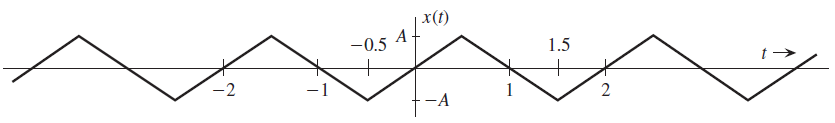


$$T_0=2$$



$$\omega_0=\pi$$



$$x\left(t\right)=\left\lbrace \begin{array}{cc}
2t & \left|t\right|<\frac{1}{2}\\
2\left(1-t\right) & \frac{1}{2}<t<\frac{3}{2}
\end{array}\right.$$



$$a_0=0$$



$$a_n=\int_{\frac{-1}{2}}^{\frac{1}{2}} 2t cos(n\pi t) dt+\int_{\frac{1}{2}}^{\frac{3}{2}} 2(1-t) cos(n\pi t) dt$$



$$b_n=\int_{\frac{-1}{2}}^{\frac{1}{2}} 2t sen(n\pi t) dt+\int_{\frac{1}{2}}^{\frac{3}{2}} 2(1-t) sen(n\pi t) dt$$


Para obtener la serie de forma exponencial sacamos los elementos D


$$D_0=a_0=0$$


Aplicando la fórmula $D_n=\frac{a_n}{2}-\frac{b_n}{2}j$ obtenemos:


$$D_n=-\frac{4}{n^2\pi^2}sen\left(\frac{n\pi}{2}\right)j$$


Serie de fourier exponencial compleja:


$$S_f(t)=\sum_{n=-\infty}^{\infty}-\frac{4}{n^2\pi^2}sen\left( \frac{n\pi}{2}\right)je^{n\pi jt}$$


Para obtener la serie en forma trigonometrica compacta usamos las fórmulas de conversión a $C_n$ y $\theta_n$


$$C_0=0
$$



$$C_n=2||D_n||$$
 
$$\Rightarrow$$
 
$$C_n=\frac{8}{n^2\pi^2}sen\left(\frac{n\pi}{2}\right)j$$



$$\theta_n=\angle D_n$$


 Serie de Fourier Trigonometrica compacta es:


$$S_f(t)=\sum_{n=1}^{\infty}\frac{8}{n^2\pi^2}cos(n\pi t+\theta_n)$$
     

Donde $\theta_n =\left\lbrace \begin{array}{cc}
0 & n=1,5,9,\ldotp \ldotp \ldotp \\
\pi  & n=3,7,11,\ldotp \ldotp \ldotp 
\end{array}\right.$

**Usando la función sfc:**

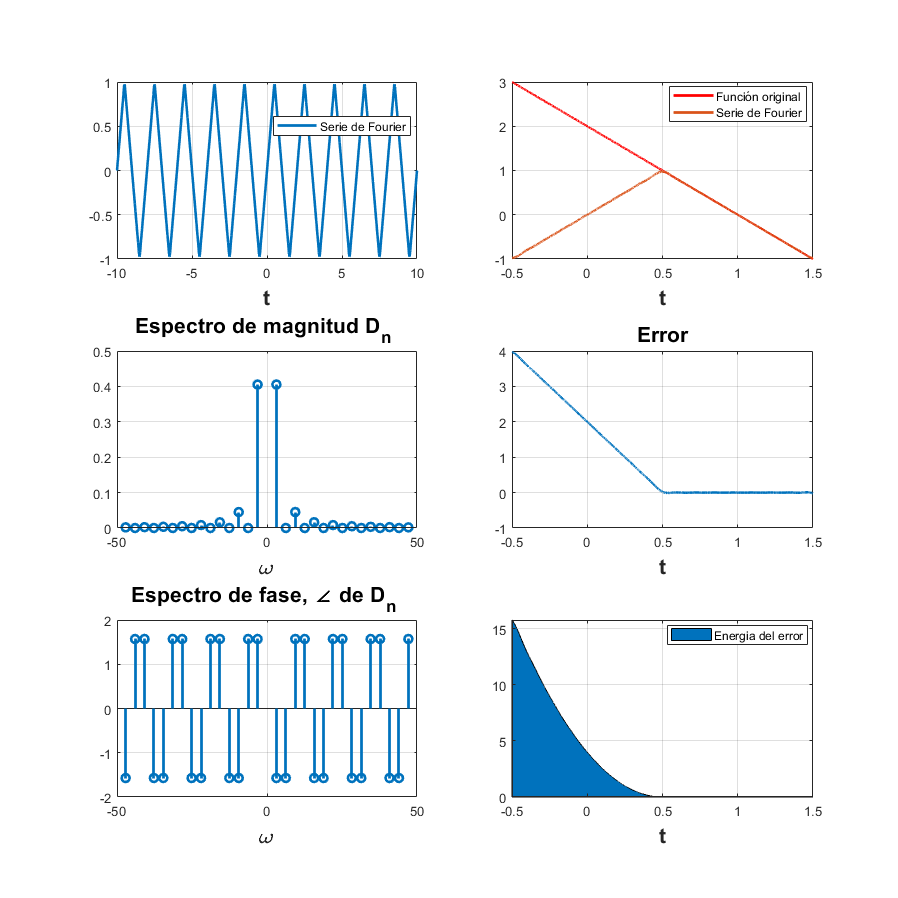

d0=0;
dn=@(n) -(4./((n.^2).*(pi^2))).*sin((n.*pi)./2).*1j;
t0=-1/2;
tf=3/2;
f=@(t) ((-1/2)<=t<(1/2)).*(2.*t)+((1/2)<=t<=(3/2)).*(2.*(1-t));
armo=15;
a=-10;
b=10;
i=1;
sfc(t0,tf,dn,d0,f,armo,a,b,i)

### Ejemplo 6.4

Encuentra la serie de Fourier de la señal pulso cuadrado mostrada en la siguiente figura.

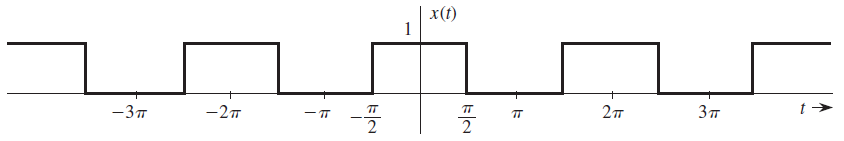


$$T_0=2\pi$$



$$\omega_0=1$$


Tenemos:


$$x\left(t\right)=\left\lbrace \begin{array}{cc}
1 & -\frac{\pi }{2}<t<\frac{\pi }{2}\\
0 & \frac{\pi }{2}<t<\frac{3\pi }{2}
\end{array}\right.$$



$$a_0=\frac12$$



$$a_n=\frac{2}{n\pi}sen\left(\frac{n\pi}{2}\right)$$



$$b_n=0$$



$$C_0=\frac{1}{2}$$



$$C_n=\left\{\begin{array}{ll}
0 & n \text { par } \\
\frac{2}{\pi n} & n \text { impar }
\end{array}\right.
$$



$$\theta_0=0$$



$$\theta_{n}=\left\{\begin{array}{ll}
0 & \text { para todo } n \neq 3,7,11,15, \ldots \\
-\pi & n=3,7,11,15, \ldots
\end{array}\right.$$


Serie de Fourier trigonométrica:


$$S_f(t)=\frac{1}{2}+\sum_{n=1}^{\infty}\frac{2}{n\pi}cos(nt+\theta_n)$$
    

Donde $\theta_n =\left\lbrace \begin{array}{cc}
0 & n=1,5,9,\ldotp \ldotp \ldotp \\
\pi  & n=3,7,11,\ldotp \ldotp \ldotp 
\end{array}\right.$

Usando la formula de conversión para obtener los valores ***D***:


$$D_0=\frac{1}{2}$$



$$D_n=\frac{a_n}{2}-\frac{b_n}{2}j$$
 
$$\Rightarrow$$
 
$$D_n=\frac1{n\pi}sen\left(\frac{n\pi}{2}\right)$$


Serie de Fourier exponencial compleja:


$$S_f(t)=\sum_{n=1}^{\infty}\frac1{n\pi}sen\left(\frac{n\pi}{2}\right)e^{njt}$$
   

(n≠0)

**Haciendo uso de la función sfc:**

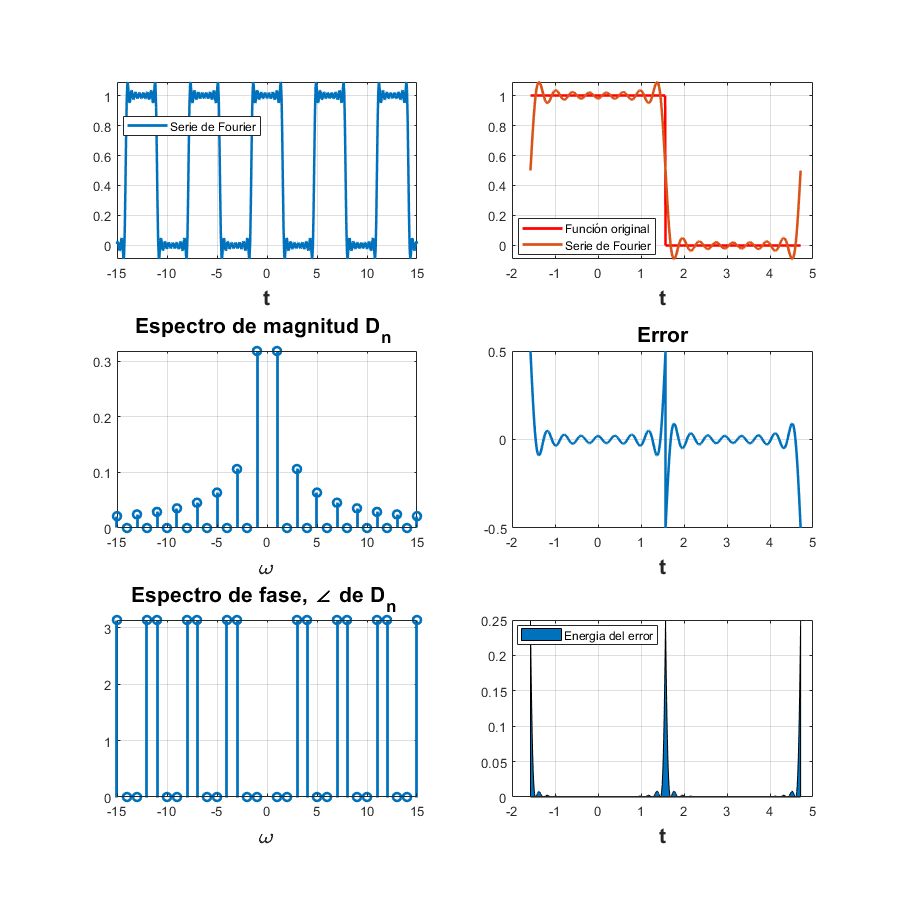

d0=1/2;
dn=@(n) (1./(n.*pi)).*sin((n.*pi)/2);
t0=-pi/2;
tf=(3.*pi)/2;
f=@(t) mod(t+pi/2,2*pi)<=pi;
armo=15;
a=-15;
b=15;
i=2;
sfc(t0,tf,dn,d0,f,armo,a,b,i)

### PR08 

#### Serie 1

Encuentra la expresión de la serie de Fourier para la señal $f(t)=t$ en el intervalo [-1,1]

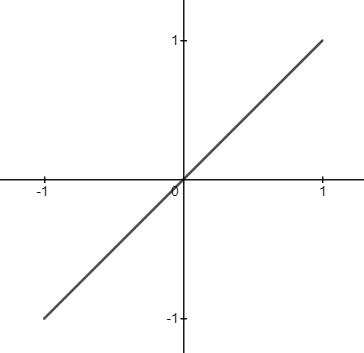


$$T_0=2$$



$$\omega_0=\pi$$


Encomntramos los valores an y bn:


$$a_0=0$$



$$a_n=0
$$



$$b_n=-\frac{2}{\pi n}cos(\pi n)$$


Usando la formulas de conversión para obtener los valores D:


$$D_0=0$$



$$D_n=\frac{a_n}{2}-\frac{b_n}{2}j$$
  
$$\Rightarrow$$
  
$$D_n=\frac{1}{\pi n}cos(\pi n)j$$


Serie de Fourier exponencial compleja:


$$S_f(t)=\sum_{n=-\infty}^{\infty}\frac1{n\pi}sen\left(\frac{n\pi}{2}\right)e^{njt}$$


Serie de Fourier trigonométrica compacta:


$$S_f(t)=\sum_{n=1}^{\infty}\frac{2}{\pi n}cos(\pi n)jcos(n\pi t+\phi_n)$$


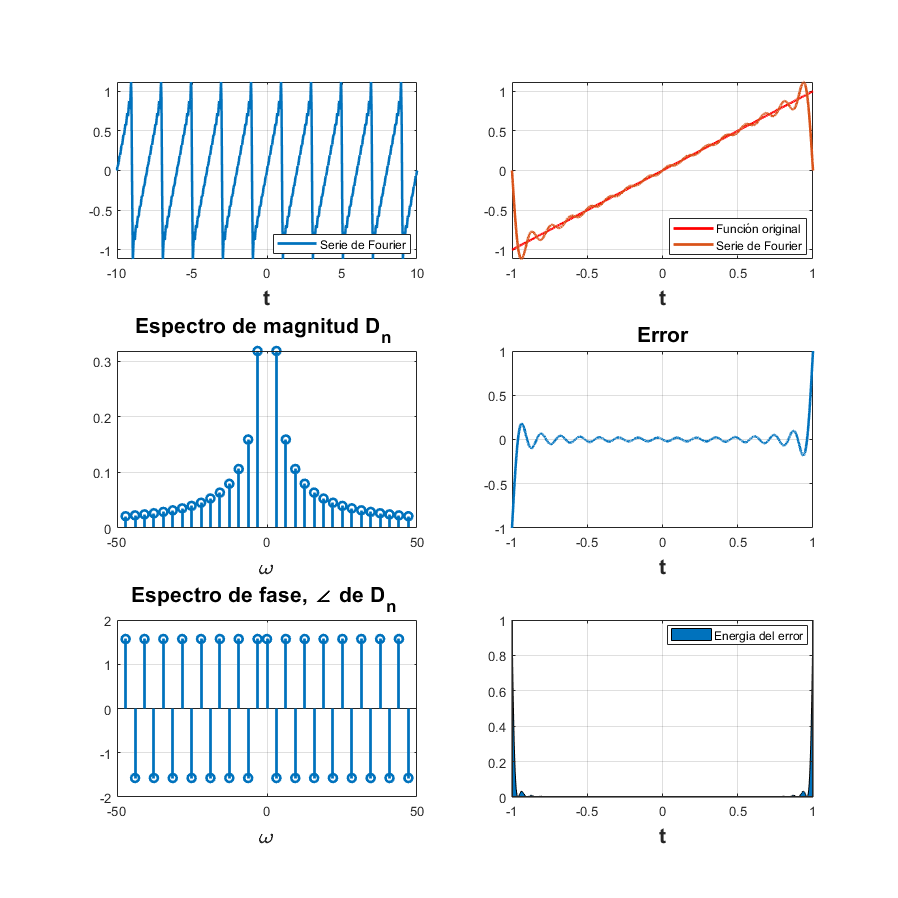

d0=0;
dn=@(n) (cos(n.*pi).*1j)/(n.*pi);

t0=-1;
tf=1;
f=@(t) t;
armo=15;
a=-10;
b=10;
i=3;
sfc(t0,tf,dn,d0,f,armo,a,b,i)

#### Serie 2

Encuentra la expresión de la serie de Fourier para la función $f(t)=t^{2}$ en el intervalo [-2,2]

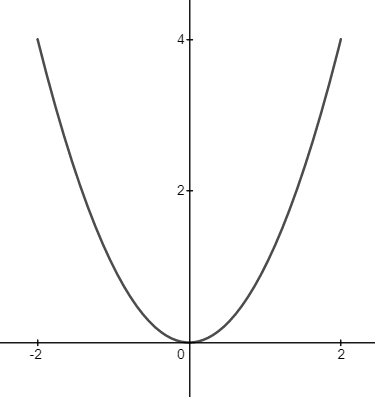


$$T_0=4$$



$$\omega_0=\frac{\pi}{2}$$


Valores de an y bn:


$$a_0=\frac{4}{3}$$



$$a_n=\frac{16}{\pi^2n^2}cos(\pi n)
$$



$$b_n=0$$


Usamos la formulas de conversión para obtener los valores ***D***:


$$D_0=\frac{4}{3}$$



$$D_n=\frac{a_n}{2}-\frac{b_n}{2}j$$
  
$$\Rightarrow$$
  
$$D_n=\frac{8}{\pi^2n^2}cos(\pi n)$$


Serie de Fourier exponencial compleja:


$$S_f(t)=\sum_{n=-\infty}^{\infty}\frac{8}{\pi^2n^2}cos(\pi n)e^{\frac{\pi}{2}njt}$$


Valores de C:


$$C_0=\frac{4}{3}$$



$$C_n=2||D_n||$$
  
$$\Rightarrow$$
  
$$C_n=\frac{16}{\pi^2n^2}cos(\pi n)
$$



$$\phi_n=tan^{-1}\left(\frac{b_n}{a_n}\right)$$
 
$$\Rightarrow$$
  
$$\phi_n=$$

$$\left\lbrace \begin{array}{cc}
0 & n=1,5,9,\ldotp \ldotp \ldotp \\
\pi  & n=3,7,11,\ldotp \ldotp \ldotp 
\end{array}\right.$$


Serie de Fourier trigonométrica compacta:


$$S_f(t)=\frac{4}{3}+\sum_{n=1}^{\infty}\frac{16}{\pi^2n^2}cos(\pi n)
cos\left(\frac{\pi}{2}n t+\phi_n\right)$$


Donde $\phi_n=$$\left\lbrace \begin{array}{cc}
0 & n=1,5,9,\ldotp \ldotp \ldotp \\
\pi  & n=3,7,11,\ldotp \ldotp \ldotp 
\end{array}\right.$

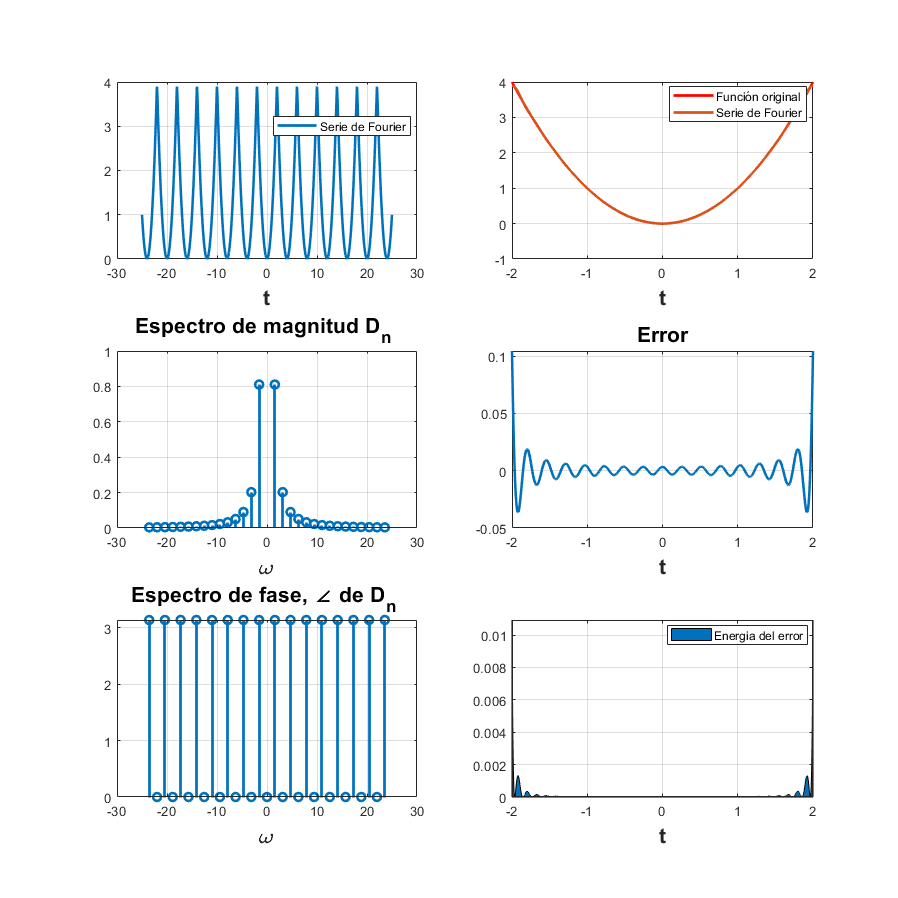

d0=4/3;
dn=@(n) (8/(n.^2.*pi^2)).*cos(n*pi);
t0=-2;
tf=2;
f=@(t) (((-2)<=t<(2)).*(t.^2));
armo=15;
a=-25;
b=25;
i=4;
sfc(t0,tf,dn,d0,f,armo,a,b,i)

### PR10

Sea una señal f(t) de periodo T, su descripción en el intervalo $\left[ \frac{-T}{2} , \frac{T}{2} \right]$es $f(t)=ae^{-at}$.Con a=2;

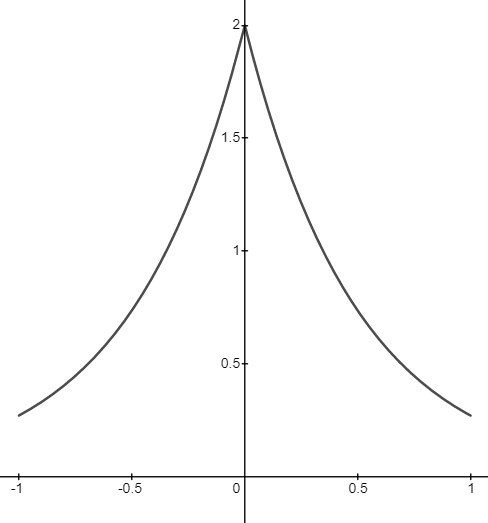


$$T_0=2$$



$$\omega_0=\pi$$



$$x\left(t\right)=\left\lbrace \begin{array}{ll}
ae^{-a\left|t\right|}  & -\frac{T}{2}\le t\le \frac{T}{2}\\
0 & \textrm{otro}\;\textrm{caso}
\end{array}\right.$$
    
$$\Rightarrow$$
   
$$x\left(t\right)=\left\lbrace \begin{array}{ll}
2e^{-2\left|t\right|}  & -1\le t\le 1\\
0 & \textrm{otro}\;\textrm{caso}
\end{array}\right.$$


Valores para an y bn:


$$a_0=1-e^{-a}$$
   
$$\Rightarrow$$
   
$$a_0=1-e^{-2}$$



$$a_n=\frac{-2a[ae^{-a}(cos(n\pi)-e^a)]}{a^2+n^2\pi^2}$$
   
$$\Rightarrow$$
  
$$a_n=\frac{-4[2e^{-2}(cos(n\pi)-e^2)]}{4+n^2\pi^2}$$



$$b_n=0$$


Usamos las formulas de conversión para obtener los valores ***D***:


$$D_0=1-e^{-2}$$



$$D_n=\frac{a^{2}(1-e^{-a}\cos(n\pi))}{a^{2}+n^{2}\pi^{2}}$$
   
$$\Rightarrow$$
  
$$D_n=\frac{4(1-e^{-2}\cos(n\pi))}{4+n^{2}\pi^{2}}$$


Serie de Fourier exponencial compleja:


$$S_f(t)=1-e^{-2}+ \sum_{n=-\infty}^{\infty}\frac{4(1-e^{-2}\cos(n\pi))}{4+n^{2}\pi^{2}}e^{\pi njt}$$


Valores de C:


$$C_0=1-e^{-2}$$



$$C_n=\sqrt{(a_n)^2+(b_n)^2}$$
  
$$\Rightarrow$$
  
$$C_n=\frac{4[2e^{-2}(cos(n\pi)-e^2)]}{4+n^2\pi^2}$$



$$\phi_0=0$$



$$\phi_n=tan^{-1}\left(\frac{b_n}{a_n}\right)$$
  
$$\Rightarrow$$
  
$$\phi_n=$$

$$\left\lbrace \begin{array}{cc}
0 & n=1,5,9,\ldotp \ldotp \ldotp \\
\pi  & n=3,7,11,\ldotp \ldotp \ldotp 
\end{array}\right.$$


Serie de Fourier trigonométrica compacta queda:


$$S_f(t)=1-e^{-2}+\sum_{n=1}^{\infty}\frac{4[2e^{-2}(cos(n\pi)-e^2)]}{4+n^2\pi^2}
cos\left(\pi n t+\phi_n\right)$$


Donde $\phi_n=$$\left\lbrace \begin{array}{cc}
0 & n=1,5,9,\ldotp \ldotp \ldotp \\
\pi  & n=3,7,11,\ldotp \ldotp \ldotp 
\end{array}\right.$

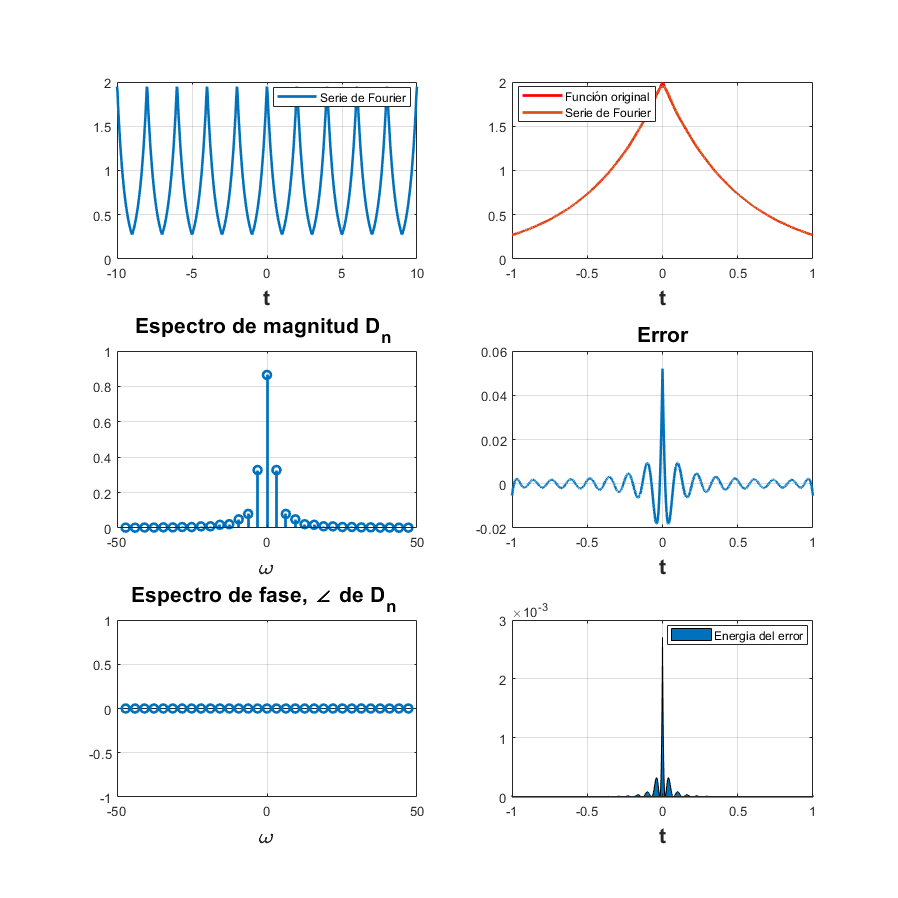

a=2;
d0=1-exp(-a);
dn=@(n) (a.^2*(1-exp(-a)*cos(n.*pi)))/(a.^2+(n.^2*pi^2));
t0=-1;
tf=1;
f=@(t) (a*exp(-a*abs(t)));
armo=15;
a=-10;
b=10;
i=5;
sfc(t0,tf,dn,d0,f,armo,a,b,i)

### Referencias

- *Lathi B.P.. (2018). LINEAR SYSTEMS AND SIGNALS. 198 Madison Avenue, New York, NY 10016: OXFORD UNIVERSITY PRESS. *

- *Ambardar A. (2007). Digital signal procesing: a moder introduction, (2nd Edition). Australia: Thomson Learning. ISNB: 9780534405090.*

- *Kamen, E. W. Heck, B.S, (2008). Fundamentos de señales y sistemas usando la web y Matlab, (3a Edición), México: Person Education, ISBN: 978-9702611875*